## Tutorial 4: Two step optimization part one: the cell finding module

In this tutorial, we will discuss the first important step of optimizing EXTRACT's hyperparameters: the cell finding module. For this tutorial, we use a two-photon calcium imaging movie collected following the published guidelines, which is courtesy of Ben Yang -Parker Lab. See Parker, J.G., Marshall, J.D., Ahanonu, B. et al. Diametric neural ensemble dynamics in parkinsonian and dyskinetic states. Nature 557, 177–182 (2018). https://doi.org/10.1038/s41586-018-0090-6 Extended Data Fig 4 for more information on the imaging and experimental conditions.

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Watching the preprocessed movie

As the first step, we watch the preprocessed movie and ensure that the motion is properly corrected and the spatial filtering does not introduce significant artifacts.

M = single(h5read("D:\tests\data\h5\roi2\plane8.h5", "/mov"));
config = get_defaults([]);
M_proc = preprocess_movie(permute(M, [2 1 3]),config);
% % view_movie(M_proc(:,:,1:100))

From watching the preprocessed movie, it is rather clear that we are aiming to perform cell extraction from a rather low SNR movie, in which the cells are barely visible to the eye. Thus, cell finding module likely needs to be tweaked to account for this fact.

### Cell extraction with defaults

We start with a simple cell extraction using mainly the default parameters.

config = get_defaults([]);
% config.downsample_time_by = 1;
% config.use_gpu = 1;
output = extractor(M,config);

09-Jun-2025 11:36:11: Getting GPU information... 
	 	 	 GPU Device 1 - NVIDIA RTX A4000: Available Memory: 14.9 Gb
	 	 	 - Selecting GPU device 1 
09-Jun-2025 11:36:11: Signal extraction will run on 1 partitions serially... 
09-Jun-2025 11:36:11: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 160.5854 
	 	 	 	 minimum magnitude: 221.1217 
	 	 	 18 cells found after a total of 54 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 4 (14 removed) 
	 	 	 End of iter # 2: # cells: 4 (0 removed) 
	 	 	 End of iter # 3: # cells: 4 (0 removed) 
	 	 	 End of iter # 4: # cells: 4 (0 removed) 
	 	 	 End of iter # 5: # cells: 4 (0 removed) 
	 	 	 End of iter # 6: # cells: 4 (0 removed) 
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 4 cells.
09-Jun-2025 11:36:1

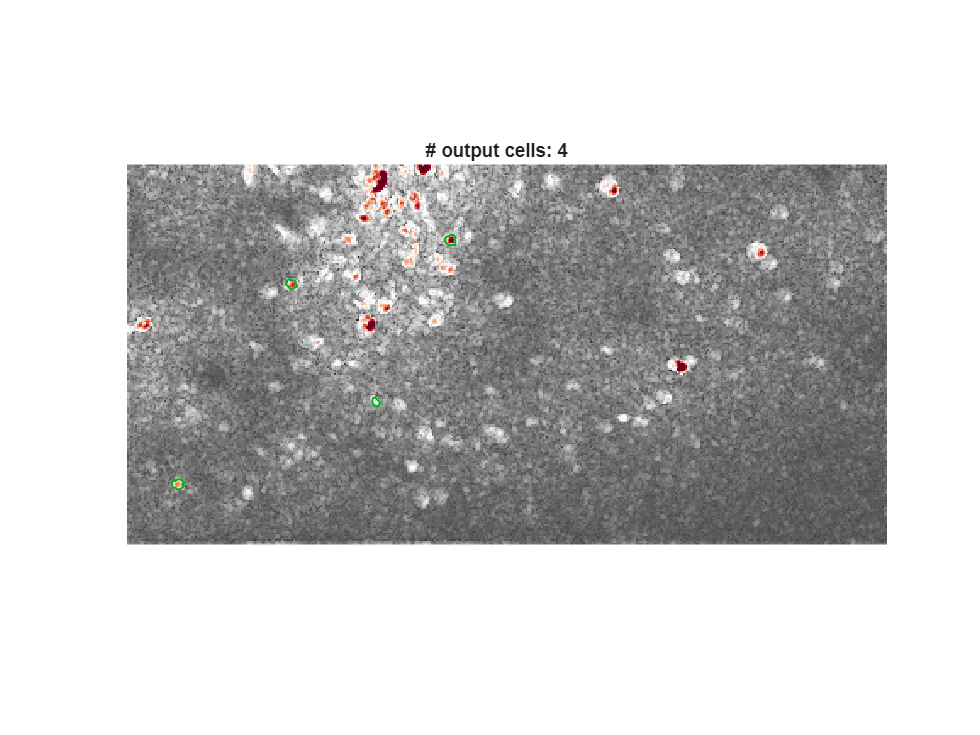

plot_output_cellmap(output,[],[],'clim_scale',[0, 0.999])

% drawnow

As expected, the cell extraction with default values missed several cells. There may be several reasons, one of which is the failure of the cell finding module. To test this, we can turn off the cell refinement process and watch the cell extraction real-time as it is happening with following the code:

09-Jun-2025 11:36:45: Getting GPU information... 
	 	 	 GPU Device 1 - NVIDIA RTX A4000: Available Memory: 14.9 Gb
	 	 	 - Selecting GPU device 1 
09-Jun-2025 11:36:45: Signal extraction will run on 1 partitions serially... 
09-Jun-2025 11:36:45: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 160.5854 
	 	 	 	 minimum magnitude: 221.1217 


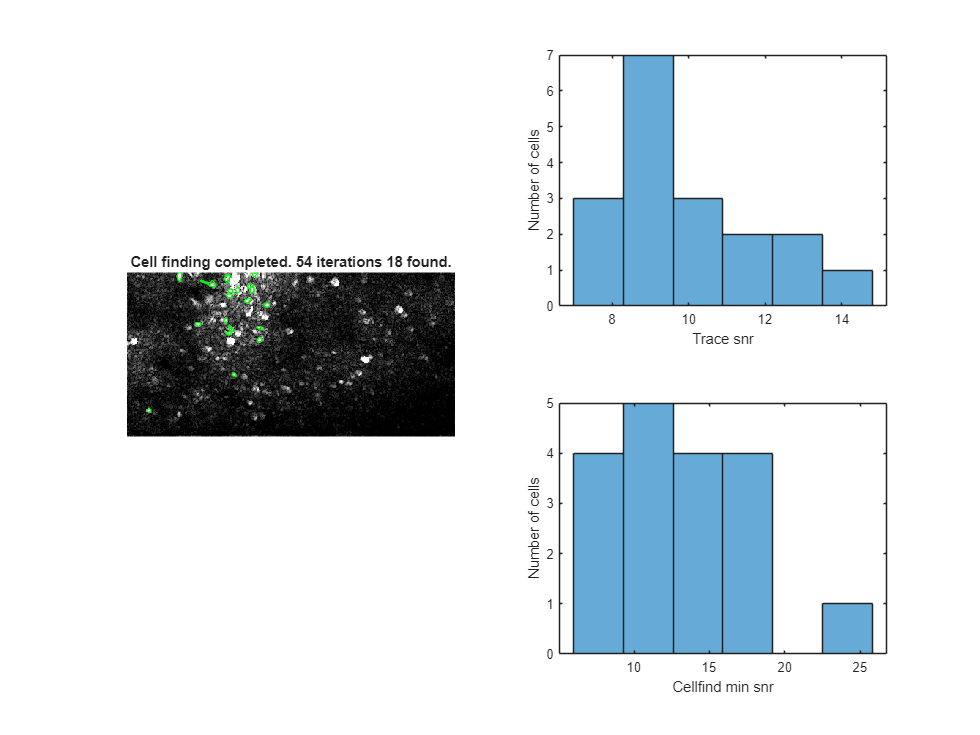

	 	 	 18 cells found after a total of 54 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Providing baseline adjusted traces with adaptive kappa... 
	 	 	 Count: 18 cells.
09-Jun-2025 11:36:51: Total of 18 cells are found.
09-Jun-2025 11:36:51: Removing duplicate cells...
09-Jun-2025 11:36:51: 18 cells were retained after removing duplicates.
09-Jun-2025 11:36:51: All done with EXTRACT! 


config.max_iter = 0;
config.visualize_cellfinding = 1;
output = extractor(M,config);

Indeed, as can be seen above, cell finding module is missing several low SNR cells that should have been identified.

### Optimizing the cell finding module

To optimize the cell finding module, we will first note that the earlier run had shown an early cutoff for the trace snr values, indicating that more cells might have been found in lower SNR values. Second, the cellfind min snr value was centered around 5 (often should be ~10-100s), a rather low value. Thus, we first pick very low values for both parameters. 

Next, since our main concern is being able to identify cells, we can also decrease the cutoff value for the spatial lowpass filter. This will allow more smoothing of the movie used for the cell finding purposes only.

09-Jun-2025 11:37:38: Signal extraction will run on 1 partitions serially... 
09-Jun-2025 11:37:38: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 40.5834 
	 	 	 	 minimum magnitude: 15.2988 


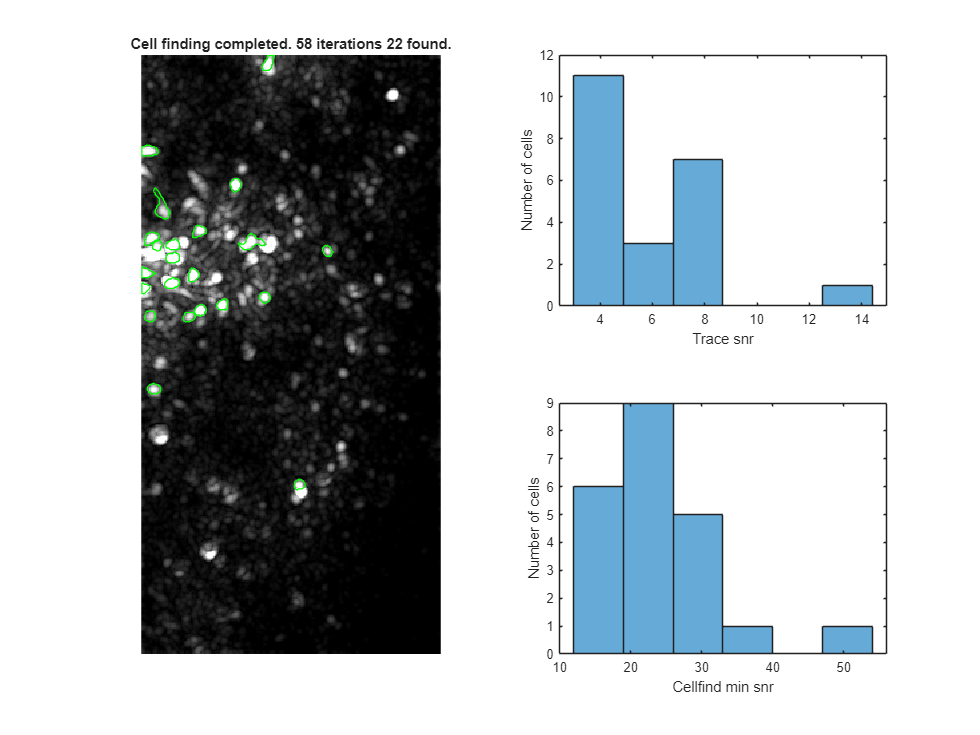

	 	 	 22 cells found after a total of 58 steps... 
	 	 	 Skipping cell refinement module...
	 	 	 Re-estimating T for all frames... 
	 	 	 Count: 22 cells.
09-Jun-2025 11:37:44: Total of 22 cells are found.
09-Jun-2025 11:37:44: Removing duplicate cells...
09-Jun-2025 11:37:44: 22 cells were retained after removing duplicates.
09-Jun-2025 11:37:44: All done with EXTRACT! 



config = get_defaults([]);
config.downsample_time_by = 4;
config.spatial_lowpass_cutoff = 1;
config.use_gpu = 0;
config.max_iter = 0;
config.visualize_cellfinding = 1;
config.cellfind_min_snr = 0;
config.thresholds.T_min_snr = 3.5;
output = extractor(M_proc,config);

And voila! We have achieved a satisfactory cell finding process, where almost all cells (but also some garbage) are found. The next tutorial will discuss how to optimize the cell refinement module, which primarily aims to cull away the false-positive candidates.